syms z
Gp = (0.3764*(z+0.9717))/(z*(z-0.9173));
F = (0.07962*(z+0.9717))/(z*(z-0.8430));
Gc = simplify((1/Gp)*(F/(1-F)));

Gc = (0.2115*z^2-0.1940)/(z^2-0.92262*z-0.07737);
Gp = (0.3764*z+0.3657)/(z^2-0.9173*z);

num = [0 0.0000145 0.0000141];
den = [1 -1.8430 0.8430]

den =     1.0000   -1.8430    0.8430


G = tf(num, den, 0.007)


G =
 
  1.45e-05 z + 1.41e-05
  ---------------------
  z^2 - 1.843 z + 0.843
 
Sample time: 0.007 seconds
Discrete-time transfer function.



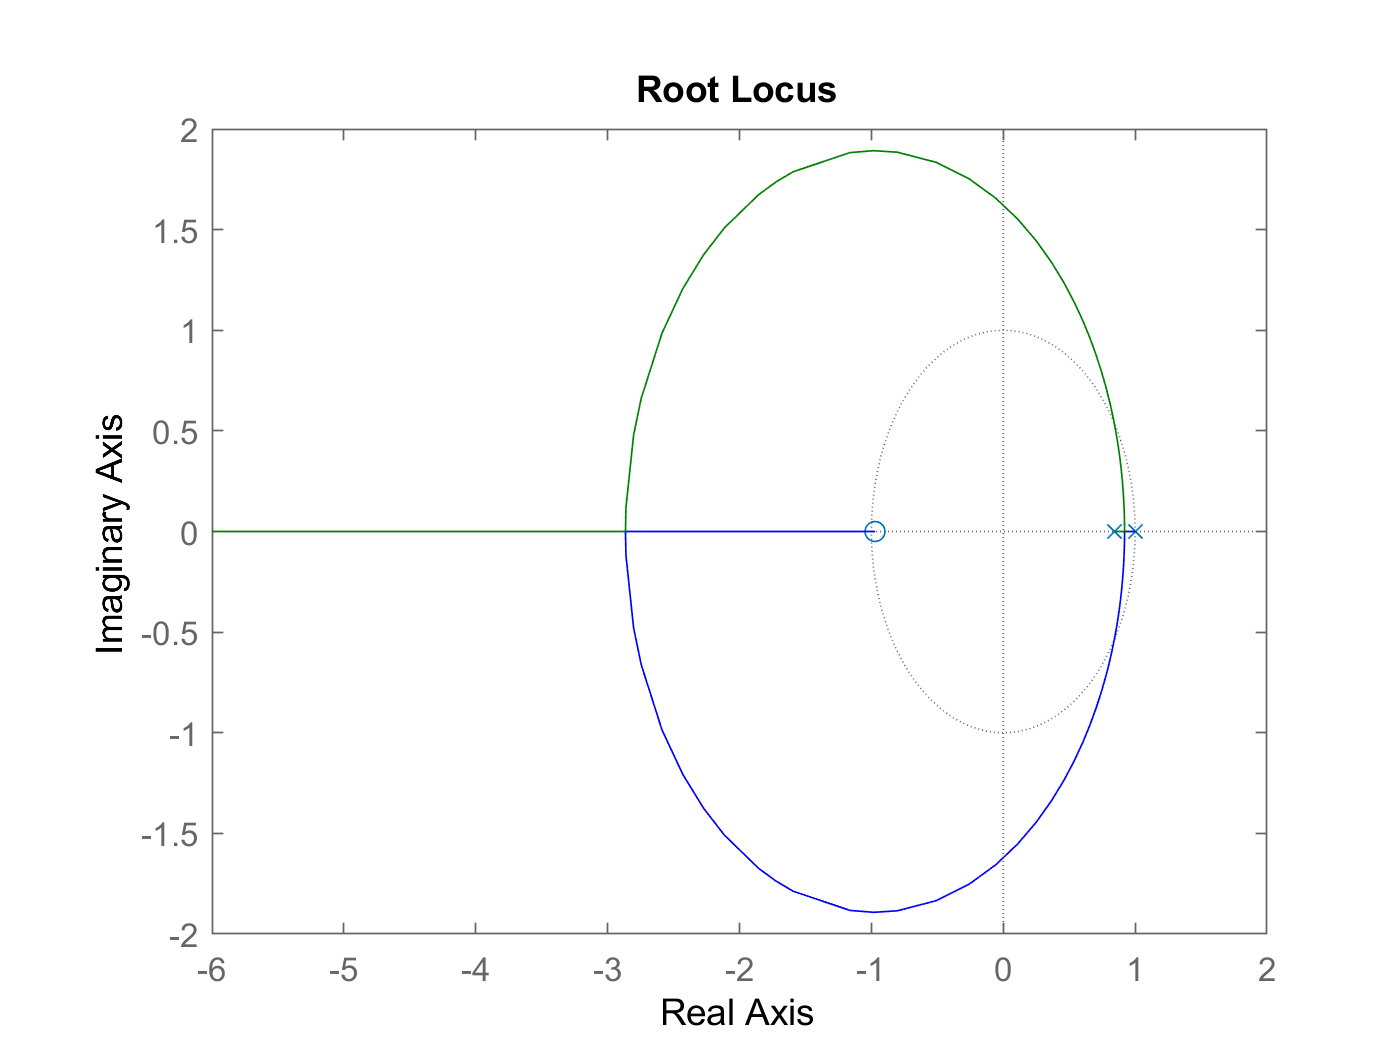

rlocus(G);